## Parte 3 - Speech Quantiation 

## Exercício 2.1

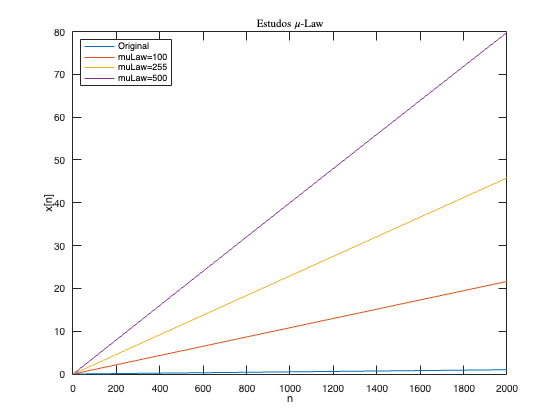

addpath("mcclellan/mcclellan/Functions/")
load("mcclellan/mcclellan/Data/s5.mat");

% Letra a)
inputVector = 0:0.0005:1;

muLaw_100 = mulaw(inputVector,100);
muLaw_255 = mulaw(inputVector,255);
muLaw_500 = mulaw(inputVector,500);

figure
plot(inputVector);
 title("Vetor de entrada"); 
 ylabel('x[n]');xlabel('n');
hold on
plot(muLaw_100);
title('$\mu$=100','Interpreter','Latex');
 ylabel('x[n]');xlabel('n');

plot(muLaw_255);
title('$\mu$=255','Interpreter','Latex');
 ylabel('x[n]');xlabel('n');

plot(muLaw_500);
title('$\mu$=500','Interpreter','Latex');
 ylabel('x[n]');xlabel('n');

axis([0 2000 0 80])
legend("Original","muLaw=100","muLaw=255","muLaw=500");
legend('Location','northwest')
title('Estudos $\mu$-Law','Interpreter','Latex');

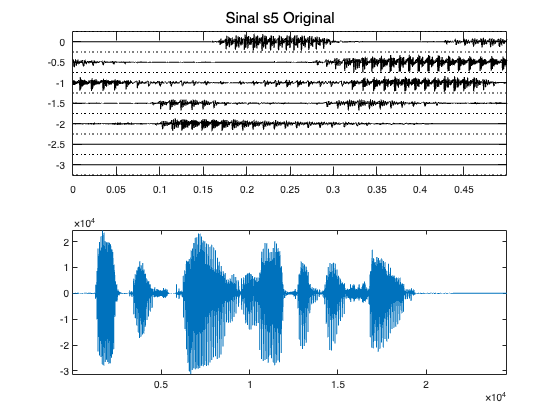


% Letra b)

figure
subplot(2,1,1);
striplot(s5,8000,4000);
subplot(2,1,2);
plot(s5)
sgtitle('Sinal s5 Original');
axis tight

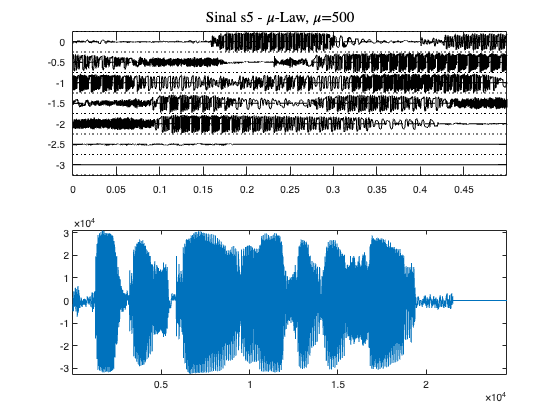


muLaw_255_s5 = mulaw(s5,255);
figure
subplot(2,1,1);
striplot(muLaw_255_s5,8000,4000);
subplot(2,1,2);
plot(muLaw_255_s5)
sgtitle('Sinal s5 - $\mu$-Law, $\mu$=500','Interpreter','Latex');
axis tight

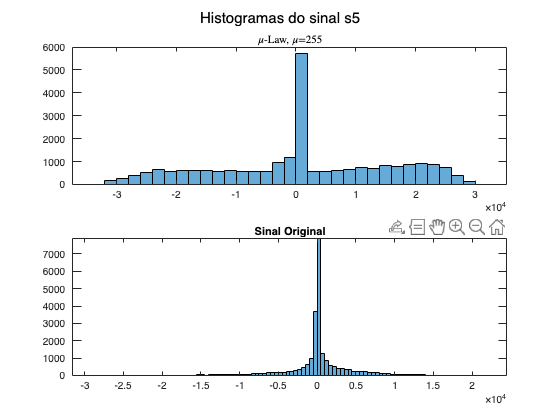


muLaw_255_s5 = mulaw(s5,255);
figure
subplot(2,1,1);
histogram(muLaw_255_s5);
title('$\mu$-Law, $\mu$=255','Interpreter','Latex')
subplot(2,1,2);
histogram(s5);
title('Sinal Original');
sgtitle('Histogramas do sinal s5');
axis tight

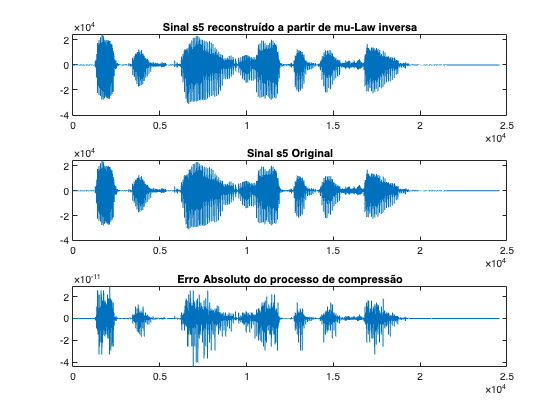

% Letra c) 
% Função no arquivo mulawinv.m 

inv_muLaw_255_s5 = mulawinv(muLaw_255_s5,255);
figure
subplot(3,1,1)
plot(inv_muLaw_255_s5);
title('Sinal s5 reconstruído a partir de mu-Law inversa');

subplot(3,1,2)
plot(s5);
title('Sinal s5 Original');
subplot(3,1,3)
plot(s5-inv_muLaw_255_s5);
title('Erro Absoluto do processo de compressão')

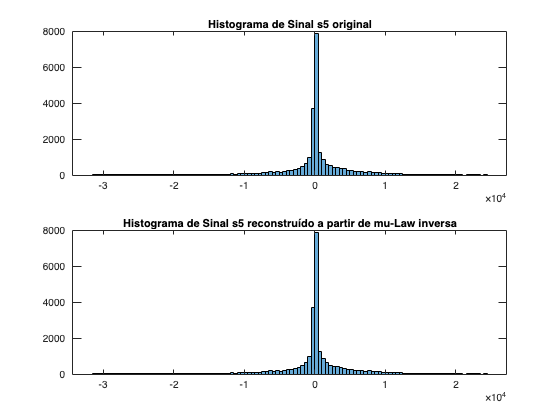


figure 
subplot(2,1,1)

histogram(s5);
title('Histograma de Sinal s5 original');
subplot(2,1,2)

histogram(inv_muLaw_255_s5);
title('Histograma de Sinal s5 reconstruído a partir de mu-Law inversa');